% 6 DoF Comparison
% Nelder-Mead Simplex Method vs. Hill Climbing
% Simplex First

tolerance = 1e-1;

% focus z-coord relative to the center of the waveguide
focus = 2;
% number of points
pts = 10;
Nw = 4.0;
Gw = 2.0;
% generate some possible fiber positions
[X1, Y1, Z1] = meshgrid(linspace(-Nw,Nw,pts), ...
                        linspace(-Nw,Nw,pts), ...
                        linspace(-Gw,Gw,pts));
[X2, Y2, Z2] = meshgrid(linspace(-Nw+2,Nw+2,pts), ...
                        linspace(-Nw+2,Nw+2,pts), ...
                        linspace(-Gw,Gw,pts));
moves = hill_climb_moves(3)

moves =     -1    -1    -1
    -1    -1     0
    -1    -1     1
    -1     0    -1
    -1     0     0
    -1     0     1
    -1     1    -1
    -1     1     0
    -1     1     1
     0    -1    -1



iterations = 1;
initial_conditions = [];
convergence = zeros(1,iterations);

for i = 1:iterations
    % generate new random initial conditions
    p = rand(1,3)
    [p_star,steps] = hill_climbing(@I3,p,moves,0.01)
    if norm([0 0 1] - p_star) < tolerance
        convergence(1,i) = 1;
    end
end

p =     0.8147    0.9058    0.1270


p_star =     0.0047   -0.0042    0.9970


steps = 92

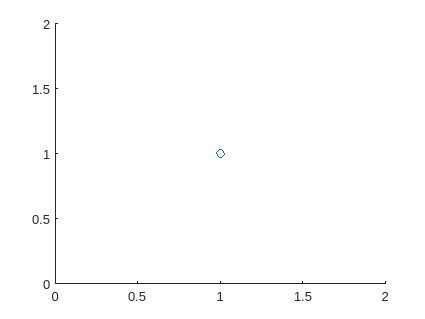

scatter(1:iterations, convergence)


moves = hill_climb_moves(6)

moves =     -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1     0
    -1    -1    -1    -1    -1     1
    -1    -1    -1    -1     0    -1
    -1    -1    -1    -1     0     0
    -1    -1    -1    -1     0     1
    -1    -1    -1    -1     1    -1
    -1    -1    -1    -1     1     0
    -1    -1    -1    -1     1     1
    -1    -1    -1     0    -1    -1



iterations = 1;
initial_conditions = [];
convergence = zeros(1,iterations);

% for i = 1:iterations
%     % generate new random initial conditions
%     p = rand(1,6)
%     [p_star,steps] = hill_climbing(@I6,p,moves,0.001)
%     if norm([0 0 1 0 0 1] - p_star) < tolerance
%         convergence(1,i) = 1;
%     end
% end
%scatter(1:iterations, convergence)

p = 2*rand(7, 6);

[sol,num_iter] = nelder_mead(p,@obj, 0)

n_feval = 143

iter = 76

sol =     1.2282    1.1955    0.4882    1.2277    1.1952    1.4875


num_iter = 143

I6(sol)

ans = 1.0000

function objective = obj(p)
objective = -I6(p);
end
function [p_star,steps] = hill_climbing(f, p0, moves, step_size)
num_moves = length(moves);
moves = moves * step_size;

threshold = 1e-6;
pos_moves = [];
steps = 0;

p_star = p0;

while 1 == 1
    next_fun_val = zeros(num_moves, 1);
    steps = steps + 1;
    for i = 1:num_moves
        next_fun_val(i) = f(p_star + moves(i,:));
    end
    [max_val, pos] = max(next_fun_val);
    p_star_new = p_star+moves(pos,:);
    pos_moves = [pos_moves; p_star_new];
    if norm(p_star_new - p_star) < threshold
        %steps = [steps; p_star];
        p_star = p_star_new;
        break;
    end
    p_star = p_star_new;
    %steps = [steps; p_star];
end

end
function moves = hill_climb_moves(num_var)
% returns the moves that could be performed during hill climbing
% generate all combinations, permute them
moves = [];
for num_ones = 0:1:num_var
    for num_zeros = 0:1:num_var-num_ones
        num_minus_ones = num_var - num_ones - num_zeros;
        v = [ones(1,num_ones),zeros(1,num_zeros),-1.*ones(1,num_minus_ones)];
        moves = [moves; perms(v)];
    end
end
% remove redundancies
moves = unique(moves, 'rows');
% for 3 possible moves per coordinate, for 6 var total, should have 3^6=729
end

function intensity = I3(p)
x = p(1);
y = p(2);
z = p(3);
intensity = exp(-0.25.*(x.^2 + y.^2)) + ...
            0.4*exp(-1.*((x.^2+y.^2).^(1/2)-2*2).^2) + ...
            0.2*exp(-2.*((x.^2+y.^2).^(1/2)-2*4).^2);
% focus is at z = 1
focus = 1;
% Accounting for z dependence
intensity = intensity .* exp(-0.5*(z-focus).^2);
end

function intensity = I6(p)
x = abs(p(1)-p(4));
y = abs(p(2)-p(5));
z = abs(p(3)-p(6));
intensity = exp(-0.25.*(x.^2 + y.^2)) + ...
            0.4*exp(-1.*((x.^2+y.^2).^(1/2)-2*2).^2) + ...
            0.2*exp(-2.*((x.^2+y.^2).^(1/2)-2*4).^2);
% focus is at z = 1
focus = 1;
% Accounting for z dependence
intensity = intensity .* exp(-0.5*(z-focus).^2);
end
function [ x_opt, n_feval ] = nelder_mead ( x, function_handle, flag )

%*****************************************************************************80
%
%% nelder_mead() performs the Nelder-Mead optimization search.
%
%  Licensing:
%
%    This code is distributed under the GNU LGPL license.
%
%  Modified:
%
%    19 January 2009
%
%  Author:
%
%    Jeff Borggaard
%
%  Reference:
%
%    John Nelder, Roger Mead,
%    A simplex method for function minimization,
%    Computer Journal,
%    Volume 7, Number 4, January 1965, pages 308-313.
%
%  Input:
%
%    real X(M+1,M), contains a list of distinct points that serve as 
%    initial guesses for the solution.  If the dimension of the space is M,
%    then the matrix must contain exactly M+1 points.  For instance,
%    for a 2D space, you supply 3 points.  Each row of the matrix contains
%    one point; for a 2D space, this means that X would be a
%    3x2 matrix.
%
%    handle FUNCTION_HANDLE, a quoted expression for the function,
%    or the name of an M-file that defines the function, preceded by an 
%    "@" sign;
%
%    logical FLAG, an optional argument; if present, and set to 1, 
%    it will cause the program to display a graphical image of the contours 
%    and solution procedure.  Note that this option only makes sense for 
%    problems in 2D, that is, with N=2.
%
%  Output:
%
%    real X_OPT, the optimal value of X found by the algorithm.
%
%    integer N_FEVAL, the number of function evaluations.
%

%
%  Define algorithm constants
%
  rho = 1;    % rho > 0
  xi  = 2;    % xi  > max(rho, 1)
  gam = 0.5;  % 0 < gam < 1
  sig = 0.5;  % 0 < sig < 1
  
  tolerance = 1.0E-06;
  max_feval = 250;
%
%  Initialization
% Make sure that the starting simplex is of the correct size given the
% dimensions of the problem (e.g. 3 pts for 2 var problem)
  [num_pts, num_dim] = size(x);

  if ( num_pts ~= num_dim + 1 )
    fprintf ( 1, '\n' );
    fprintf ( 1, 'NELDER_MEAD - Fatal error!\n' );
    error('  Number of points must be = number of design variables + 1\n');
  end

  if ( nargin == 2 )
    flag = 0;
  end

  if ( flag )

    xp = linspace(-5,5,101);
    yp = xp;
    for i=1:101
      for j=1:101
        fp(j,i) = feval(function_handle,[xp(i),yp(j)]);
      end
    end
    
    figure (27)
    hold on
    contour(xp,yp,fp,linspace(0,200,25))
    
    if ( flag )
      plot(x(1:2,1),x(1:2,2),'r')
      plot(x(2:3,1),x(2:3,2),'r')
      plot(x([1 3],1),x([1 3],2),'r')
      pause
      plot(x(1:2,1),x(1:2,2),'b')
      plot(x(2:3,1),x(2:3,2),'b')
      plot(x([1 3],1),x([1 3],2),'b')
    end

  end

  index = 1:num_dim + 1;

  [f    ] = evaluate ( x, function_handle ); 
  n_feval = num_dim + 1;

  [ f, index ] = sort ( f );
  x = x(index,:);
%  
%  Begin the Nelder Mead iteration.
%
  converged = 0;
  diverged  = 0;
  iter = 0;
  
  while ( ~converged && ~diverged )
      iter = iter + 1;
%    
%  Compute the midpoint of the simplex opposite the worst point.
%
    x_bar = sum ( x(1:num_dim,:) ) / num_dim;
%
%  Compute the reflection point.
%
    x_r   = ( 1 + rho ) * x_bar ...
                - rho   * x(num_dim+1,:);

    f_r   = feval(function_handle,x_r); 
    n_feval = n_feval + 1;
%
%  Accept the point:
%    
    if ( f(1) <= f_r && f_r <= f(num_dim) )

      x(num_dim+1,:) = x_r;
      f(num_dim+1  ) = f_r; 
       
      if (flag)
        title('reflection')
      end
%
%  Test for possible expansion.
%
    elseif ( f_r < f(1) )

      x_e = ( 1 + rho * xi ) * x_bar ...
                - rho * xi   * x(num_dim+1,:);

      f_e = feval(function_handle,x_e); 
      n_feval = n_feval+1;
%
%  Can we accept the expanded point?
%
      if ( f_e < f_r )
        x(num_dim+1,:) = x_e;
        f(num_dim+1  ) = f_e;
        if (flag), title('expansion'), end
      else
        x(num_dim+1,:) = x_r;
        f(num_dim+1  ) = f_r;
        if (flag), title('eventual reflection'), end
      end
%
%  Outside contraction.
%
    elseif ( f(num_dim) <= f_r && f_r < f(num_dim+1) )

      x_c = (1+rho*gam)*x_bar - rho*gam*x(num_dim+1,:);
      f_c = feval(function_handle,x_c); n_feval = n_feval+1;
      
      if (f_c <= f_r) % accept the contracted point
        x(num_dim+1,:) = x_c;
        f(num_dim+1  ) = f_c;
        if (flag), title('outside contraction'), end
      else
        [x,f] = shrink(x,function_handle,sig); n_feval = n_feval+num_dim;
        if (flag), title('shrink'), end
      end
%
%  F_R must be >= F(N_DIM+1).
%  Try an inside contraction.
%
    else

      x_c = ( 1 - gam ) * x_bar ...
                + gam   * x(num_dim+1,:);

      f_c = feval(function_handle,x_c); 
      n_feval = n_feval+1;
%
%  Can we accept the contracted point?
%
      if (f_c < f(num_dim+1))
        x(num_dim+1,:) = x_c;
        f(num_dim+1  ) = f_c;
        if (flag), title('inside contraction'), end
      else
        [x,f] = shrink(x,function_handle,sig); n_feval = n_feval+num_dim;
        if (flag), title('shrink'), end
      end

    end
%
%  Resort the points.  Note that we are not implementing the usual
%  Nelder-Mead tie-breaking rules  (when f(1) = f(2) or f(n_dim) =
%  f(n_dim+1)...
%
    [ f, index ] = sort ( f );
    x = x(index,:);
%
%  Test for convergence
%
    converged = f(num_dim+1)-f(1) < tolerance;
%   
%  Test for divergence
%
    diverged = ( max_feval < n_feval );
    
    if ( flag )
      plot(x(1:2,1),x(1:2,2),'r')
      plot(x(2:3,1),x(2:3,2),'r')
      plot(x([1 3],1),x([1 3],2),'r')
      pause
      plot(x(1:2,1),x(1:2,2),'b')
      plot(x(2:3,1),x(2:3,2),'b')
      plot(x([1 3],1),x([1 3],2),'b')
    end

  end
    n_feval
  if ( false )
    fprintf('The best point x^* was: %d %d\n',x(1,:));
    fprintf('f(x^*) = %d\n',f(1));
  end

  x_opt = x(1,:);
  
  if ( diverged )
    fprintf ( 1, '\n' );
    fprintf ( 1, 'NELDER_MEAD - Warning!\n' );
    fprintf ( 1, '  The maximum number of function evaluations was exceeded\n')
    fprintf ( 1, '  without convergence being achieved.\n' );
  end
    iter
  return
end
function f = evaluate ( x, function_handle )

%*****************************************************************************80
%
%% evaluate() handles the evaluation of the function at each point.
%
%  Licensing:
%
%    This code is distributed under the GNU LGPL license.
%
%  Modified:
%
%    19 January 2009
%
%  Author:
%
%    Jeff Borggaard
%
%  Reference:
%
%    John Nelder, Roger Mead,
%    A simplex method for function minimization,
%    Computer Journal,
%    Volume 7, Number 4, January 1965, pages 308-313.
%
%  Input:
%
%    real X(N_DIM+1,N_DIM), the points.
%
%    real FUNCTION_HANDLE ( X ), the handle of a MATLAB procedure
%    to evaluate the function.
%
%  Output:
%
%    real F(1,NDIM+1), the value of the function at each point.
%
  n_dim = size ( x, 2 );

  f = zeros ( 1, n_dim + 1 );
  
  for i = 1 : n_dim + 1
    f(i) = feval(function_handle,x(i,:));
  end

  return
end
function [ x, f ] = shrink ( x, function_handle, sig )

%*****************************************************************************
%
%% shrink() shrinks the simplex towards the best point.
%
%  Discussion:
%
%    In the worst case, we need to shrink the simplex along each edge towards
%    the current "best" point.  This is quite expensive, requiring n_dim new
%    function evaluations.
%
%  Licensing:
%
%    This code is distributed under the GNU LGPL license.
%
%  Modified:
%
%    19 January 2009
%
%  Author:
%
%    Jeff Borggaard
%
%  Reference:
%
%    John Nelder, Roger Mead,
%    A simplex method for function minimization,
%    Computer Journal,
%    Volume 7, Number 4, January 1965, pages 308-313.
%
%  Input:
%
%    real X(N_DIM+1,N_DIM), the points.
%
%    real FUNCTION_HANDLE ( X ), the handle of a MATLAB procedure
%    to evaluate the function.
%
%    real SIG, ?
%
%  Output:
%
%    real X(N_DIM+1,N_DIM), the points after shrinking was applied.
%
%    real F(1,NDIM+1), the value of the function at each point.
%
  n_dim = size ( x, 2 );

  x1 = x(1,:);
  f(1) = feval ( function_handle, x1 );

  for i = 2 : n_dim + 1
    x(i,:) = sig * x(i,:) + ( 1.0 - sig ) * x(1,:);
    f(i) = feval ( function_handle, x(i,:) );
  end
  
  return
end